此为卡尔曼滤波的代码

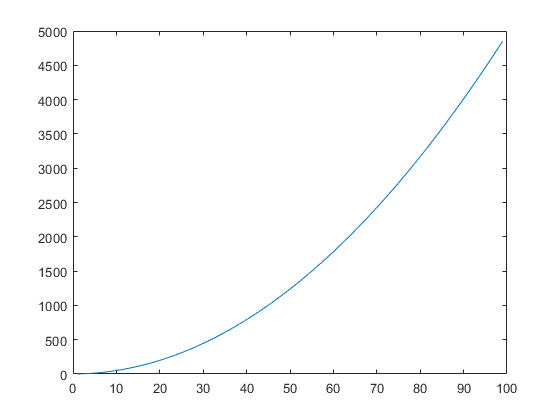

A = [0 1;0 0];
B = [1 1]';
H = [1 0];
x = [0 0]';
u = 1;
p = [0 0;0 0];
R = 0.01;
Q = [1 0;0 1];

for i = 1:99
    x = A*x+B*u;
    p = A*p*A' + Q;
    k = p*H'*(H*p*H'+R)^-1;
    x = x+k*(0.5*i^2+1  -H*x);
    p = p - k*H*p;
    sensor(i) = H*x;
end
plot(sensor);